## 1. GHZ state

We can entangle three qubits, defining the so-called GHZ state (Greenberger–Horne–Zeilinger state): $\ket{GHZ} == \frac{\ket{000} ++ \ket{111}}{\sqrt{2}}$

The final circuit we need is the following:

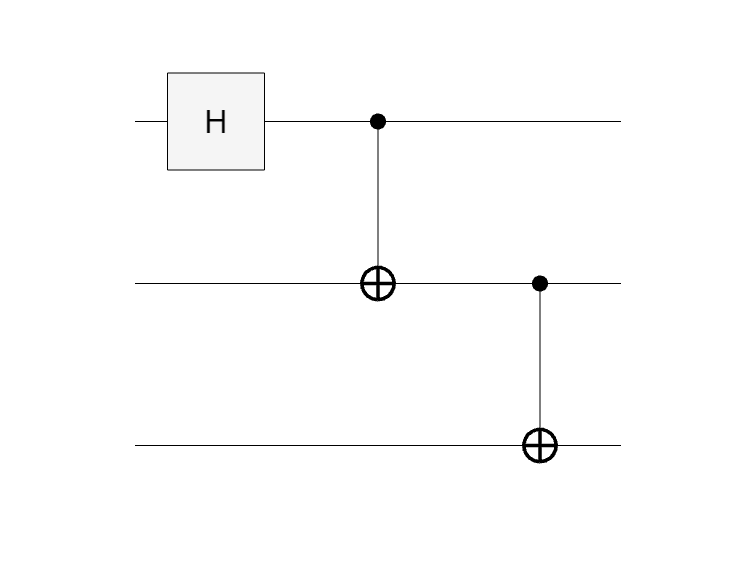

This circuit creates a two-qubit entanglement on the second qubit. Then, it sets the third qubit to 0 when the second is 1, and to 1 when the second is 0. This correctly creates an entanglement with two possible states: $\ket{000}$ and $\ket{111}$.

numQubits = 3

numQubits = 3

gates = [hGate(1);cxGate(1,2);cxGate(2,3)];
qc = quantumCircuit(gates, numQubits, Name= "GHZ_State");

Let's now plot the quantum circuit:

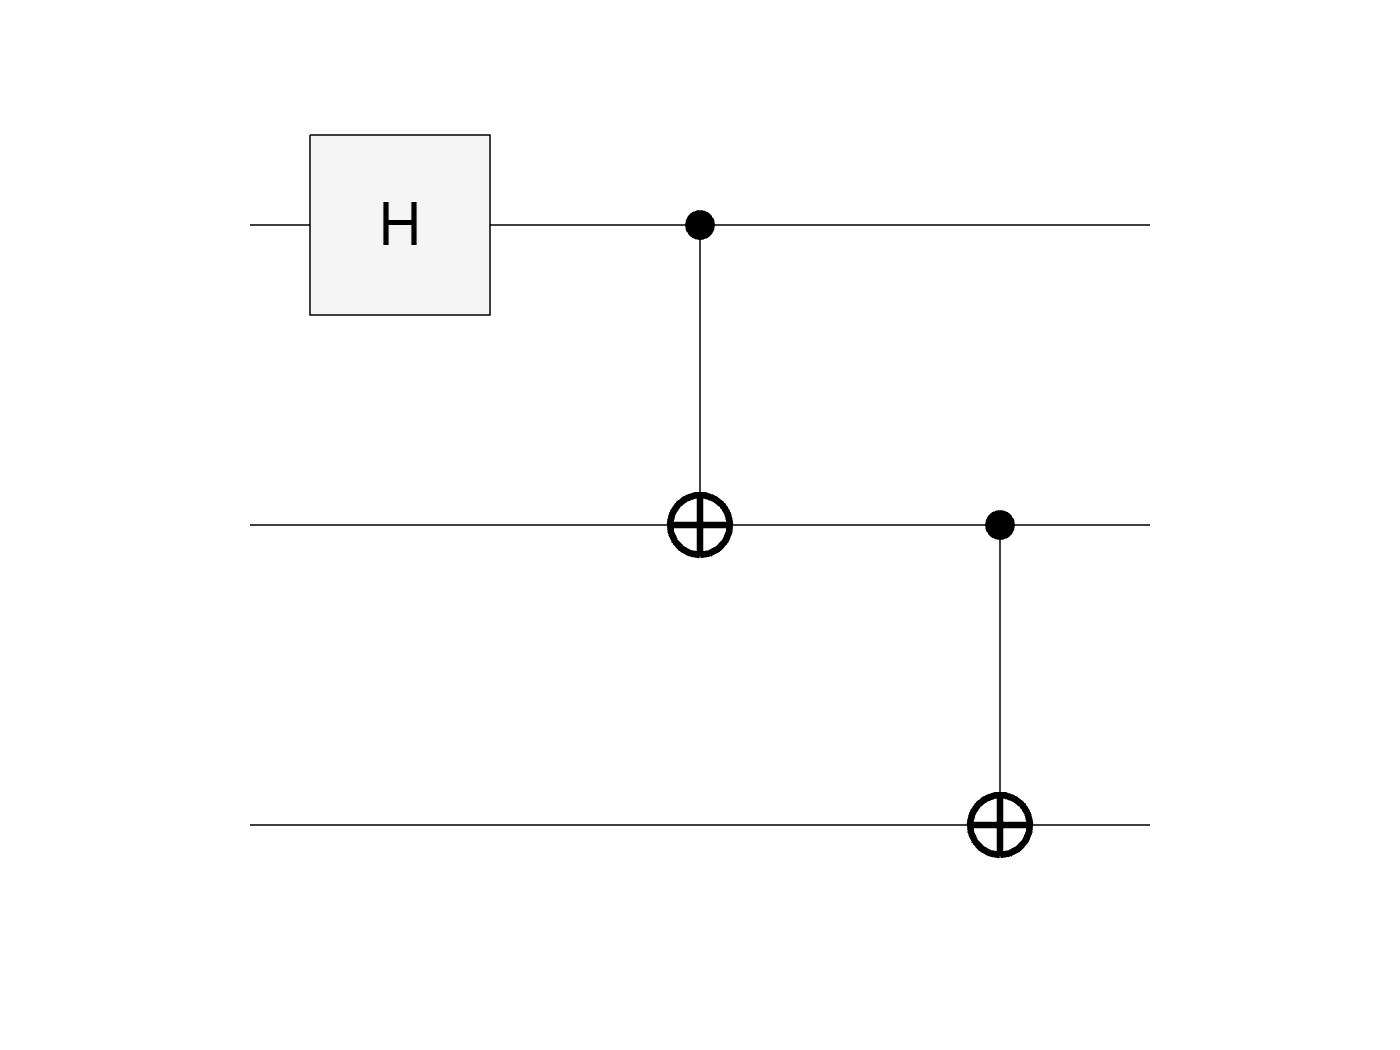

plot(qc)

Let's simulate it!

S = simulate(qc, "000")

S =   QuantumState with properties:

    BasisStates: [8×1 string]
     Amplitudes: [8×1 double]
      NumQubits: 3


We can also show such a state as a mathematical expression using Dirac bra-ket notation:

f = formula(S, basis = "Z") % the expression uses the computational basis {|0>, |1>}

f =     "0.70711 * |000> +
     0.70711 * |111>"


and we can even transform such a formula into another reference basis:

f2 = formula(S, basis="X") % we are now using the Hadamard basis {|+>, |->}

f2 =     "0.5 * |+++> +
     0.5 * |+--> +
     0.5 * |-+-> +
     0.5 * |--+>"


Let's see the final basis states and amplitudes:

T = table(S.BasisStates, S.Amplitudes, ...
    VariableNames=["Basis States","Amplitudes"])

T = 8×2 table
    Basis States    Amplitudes
    ____________    __________

       "000"         0.70711  
       "001"               0  
       "010"               0  
       "011"               0  
       "100"               0  
       "101"               0  
       "110"               0  
       "111"         0.70711  


Let's also plot the corresponding histogram:

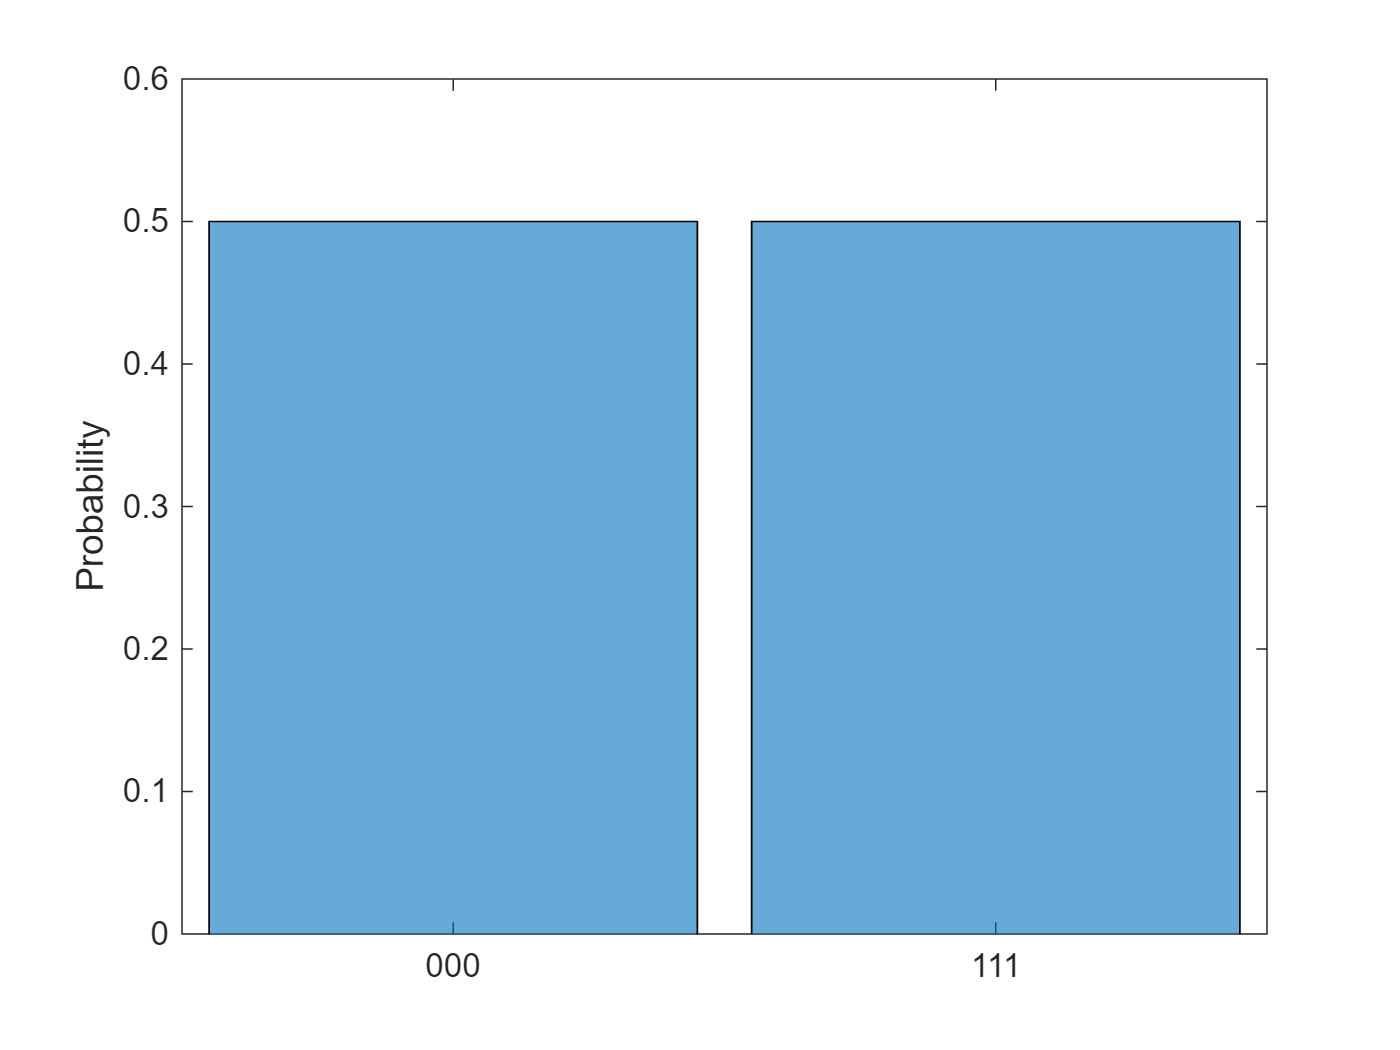

histogram(S)

M = randsample(S, 1000)

M =   QuantumMeasurement with properties:

    MeasuredStates: [2×1 string]
            Counts: [2×1 double]
     Probabilities: [2×1 double]
         NumQubits: 3


T = table(M.Counts,M.Probabilities,M.MeasuredStates, ...
    VariableNames=["Counts","Probabilities","States"])

T = 2×3 table
    Counts    Probabilities    States
    ______    _____________    ______

     502          0.502        "000" 
     498          0.498        "111" 


## 2. Unitary representations 

Given a generic quantum circuit, described as a sequence of operations, we can get the unitary matrix which represents the whole circuit:

getMatrix(qc)

ans =     0.7071         0         0         0    0.7071         0         0         0
         0    0.7071         0         0         0    0.7071         0         0
         0         0         0    0.7071         0         0         0    0.7071
         0         0    0.7071         0         0         0    0.7071         0
         0         0    0.7071         0         0         0   -0.7071         0
         0         0         0    0.7071         0         0         0   -0.7071
         0    0.7071         0         0         0   -0.7071         0         0
    0.7071         0         0         0   -0.7071         0         0         0


We can quickly verify that the given matrix is unitary:

% Let do a quick check of the unitarity of a matrix
U = getMatrix(qc);
% U'*U - I = 0
round(norm(U'*U - eye(8))) % U times the conjugate transpose of U equals I (identity matrix)

ans = 0

## 3. Using compositeGate to embed circuits

We can build a quantum circuit and integrate it into a bigger one, by using compositeGate.

Let's define a CNOT:

cnot_custom = [cxGate(1,2)];
qc_inner = quantumCircuit(cnot_custom, Name="CNOT");

Let's now embed it into a bigger quantum circuit, by using compositeGate:

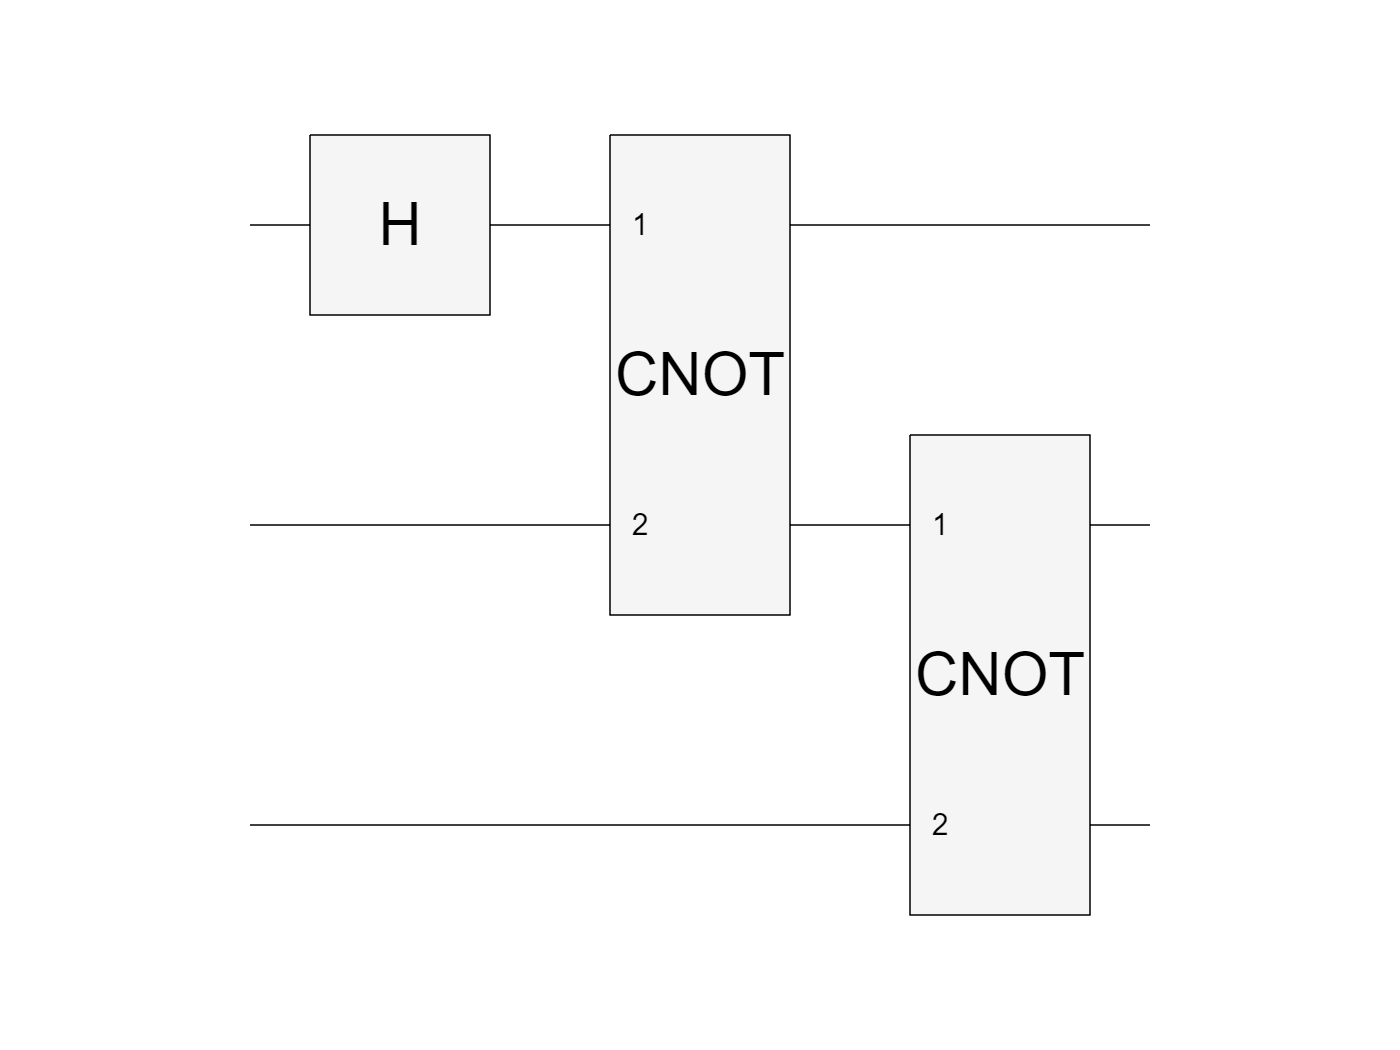

gates_appended = [hGate(1) compositeGate(qc_inner,[1 2]) compositeGate(qc_inner,[2 3])];
circ = quantumCircuit(gates_appended);
plot(circ)

As you can see, we have used the CNOT block twice, applied to different qubits. 

Let's decompose the circuit and plot:

plot(unpack(circ, "recursive"))

## 4. Statevector representation of all four bell states.

Let's see how to implement Bell States.

Let's do a simple entanglement (first Bell State).

gates = [hGate(1); cxGate(1,2)];
bell = quantumCircuit(gates);

Initialize a quantum state with different output to create all Bell states during simulation.

We can now display all four Bell states, by doing different qubit initializations.

ket = ["00","01","10","11"];
for i = 1:length(ket)
    S = simulate(bell, quantum.gate.QuantumState(ket(i)));
    formula(S)
end

ans =     "0.70711 * |00> +
     0.70711 * |11>"


ans =     "0.70711 * |01> +
     0.70711 * |10>"


ans =     "0.70711  * |00> +
     -0.70711 * |11>"


ans =     "0.70711  * |01> +
     -0.70711 * |10>"


We can also generate it automatically, for a generic number of qubit:

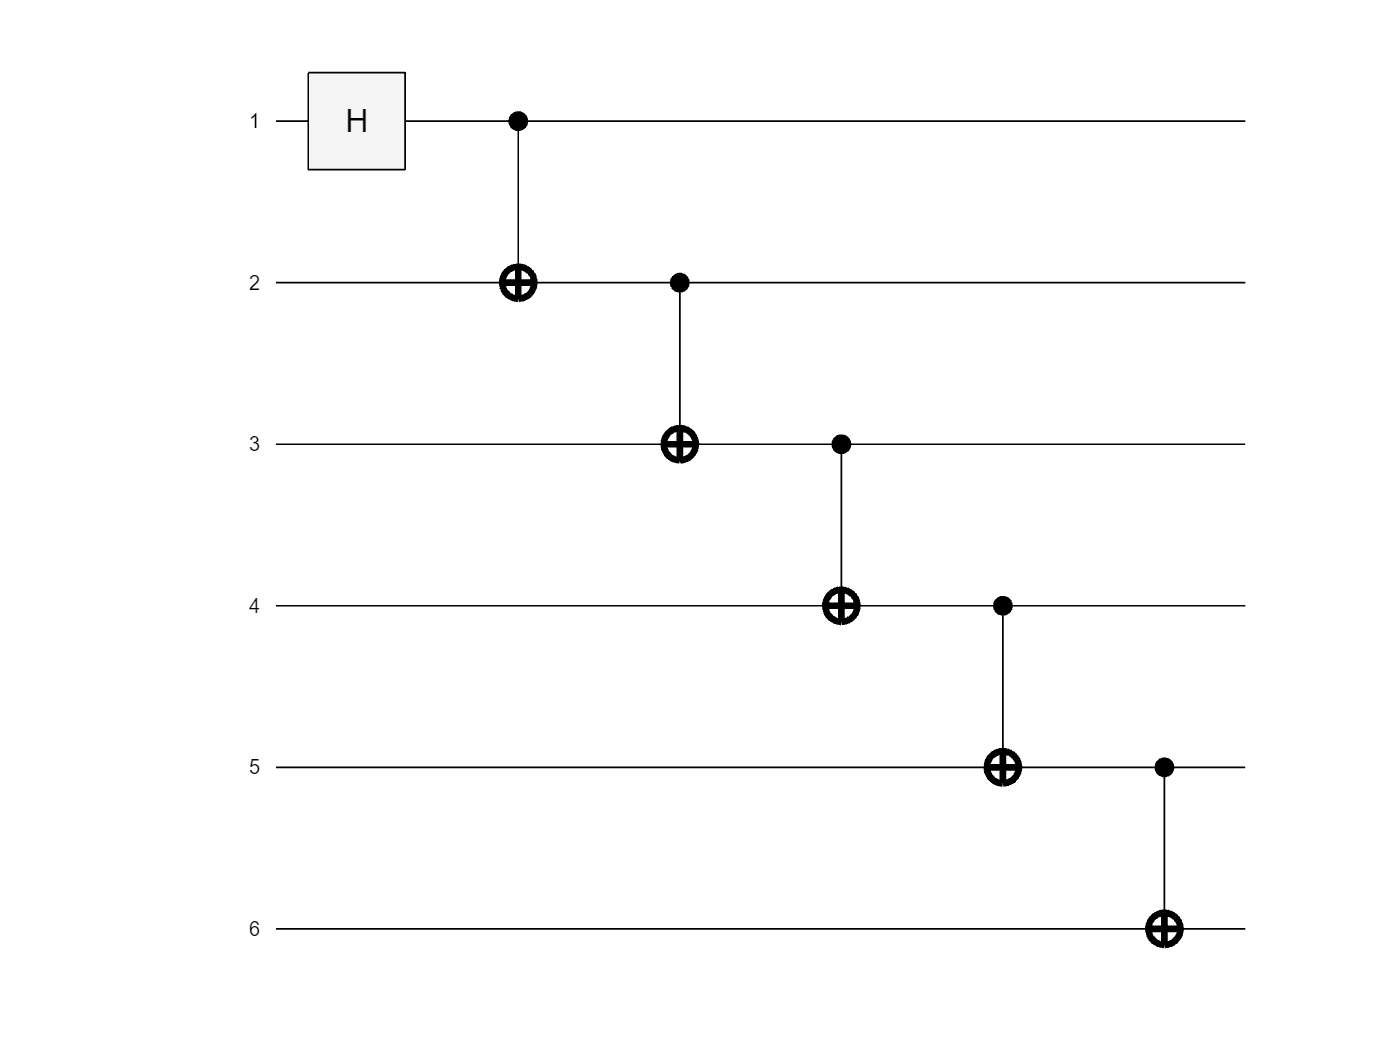

% Example of circuit generation with gates in loop
numQubits = 6;
gates = [];
gates = [gates; hGate(1)];
for i=1:numQubits
    if i ~= numQubits
        gates = [gates;cxGate(i, i + 1)];
    end
end
qc = quantumCircuit(gates,numQubits);
plot(qc)

S = simulate(qc)

S =   QuantumState with properties:

    BasisStates: [64×1 string]
     Amplitudes: [64×1 double]
      NumQubits: 6


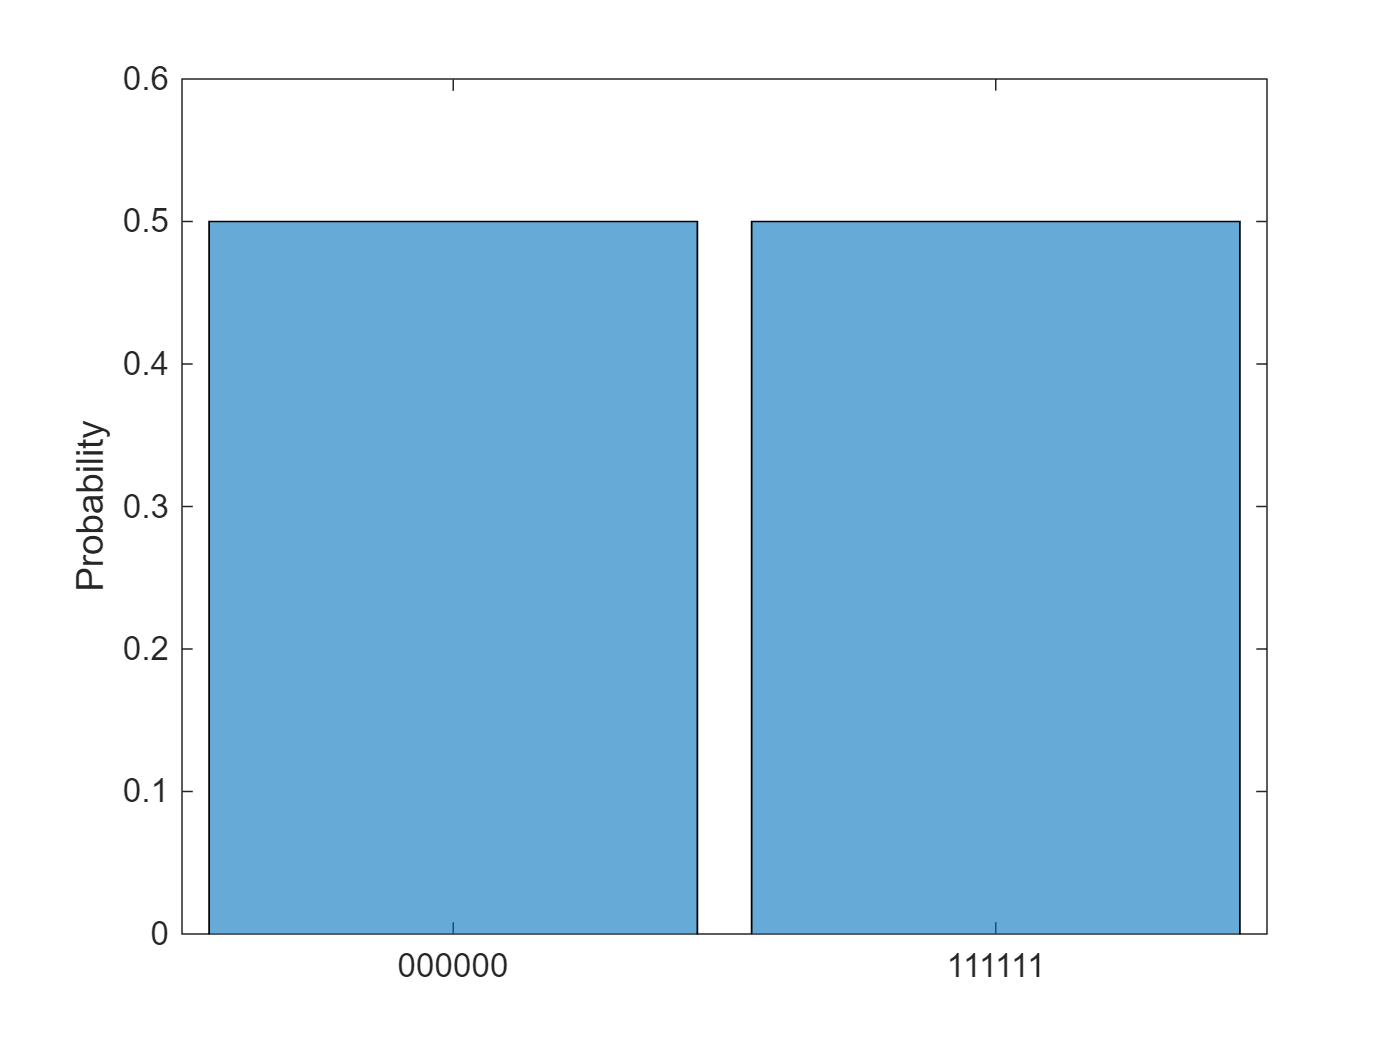

histogram(S)

## 5. Multiple gate applications on several qubits

We can apply the same gate to multiple qubits at the same time, by pasing arrays as inputs.

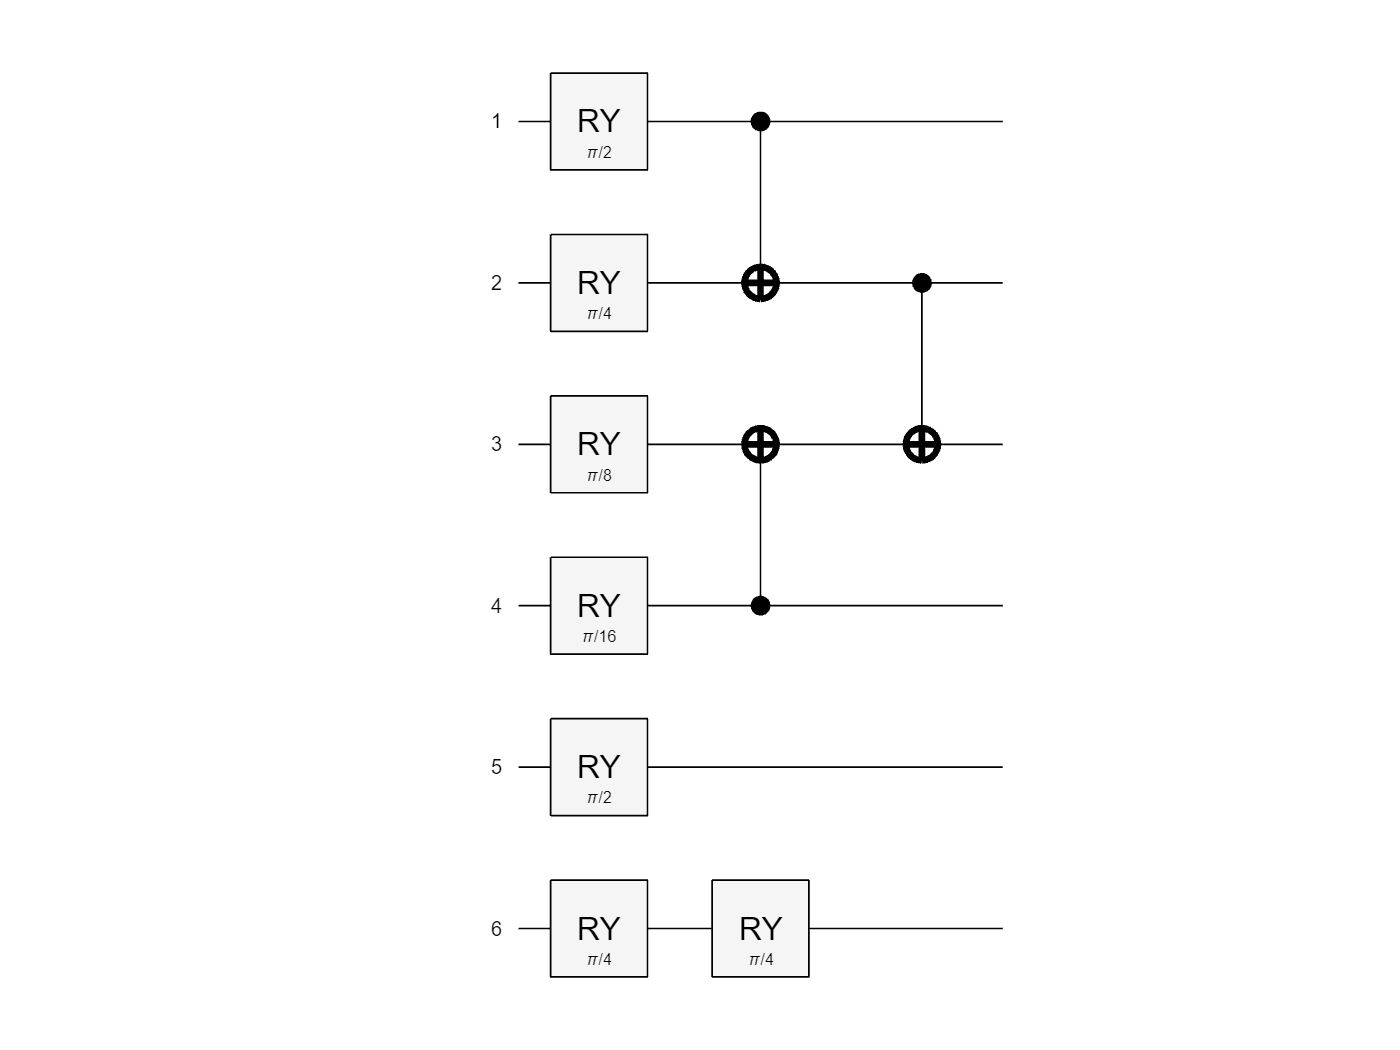

weights = [pi/2,pi/4,pi/8,pi/16,pi/2,pi/4];
numQubits = 6;
readout = 6;
paramGates = [ryGate(1:numQubits, weights(1:numQubits))
              cxGate([1 4], [2 3])
              ryGate(2, weights(numQubits:end-1))
              cxGate(2,3)
              ryGate(readout, weights(end))
              ];
circ = quantumCircuit(paramGates);
plot(circ)

S = simulate(circ)

S =   QuantumState with properties:

    BasisStates: [64×1 string]
     Amplitudes: [64×1 double]
      NumQubits: 6


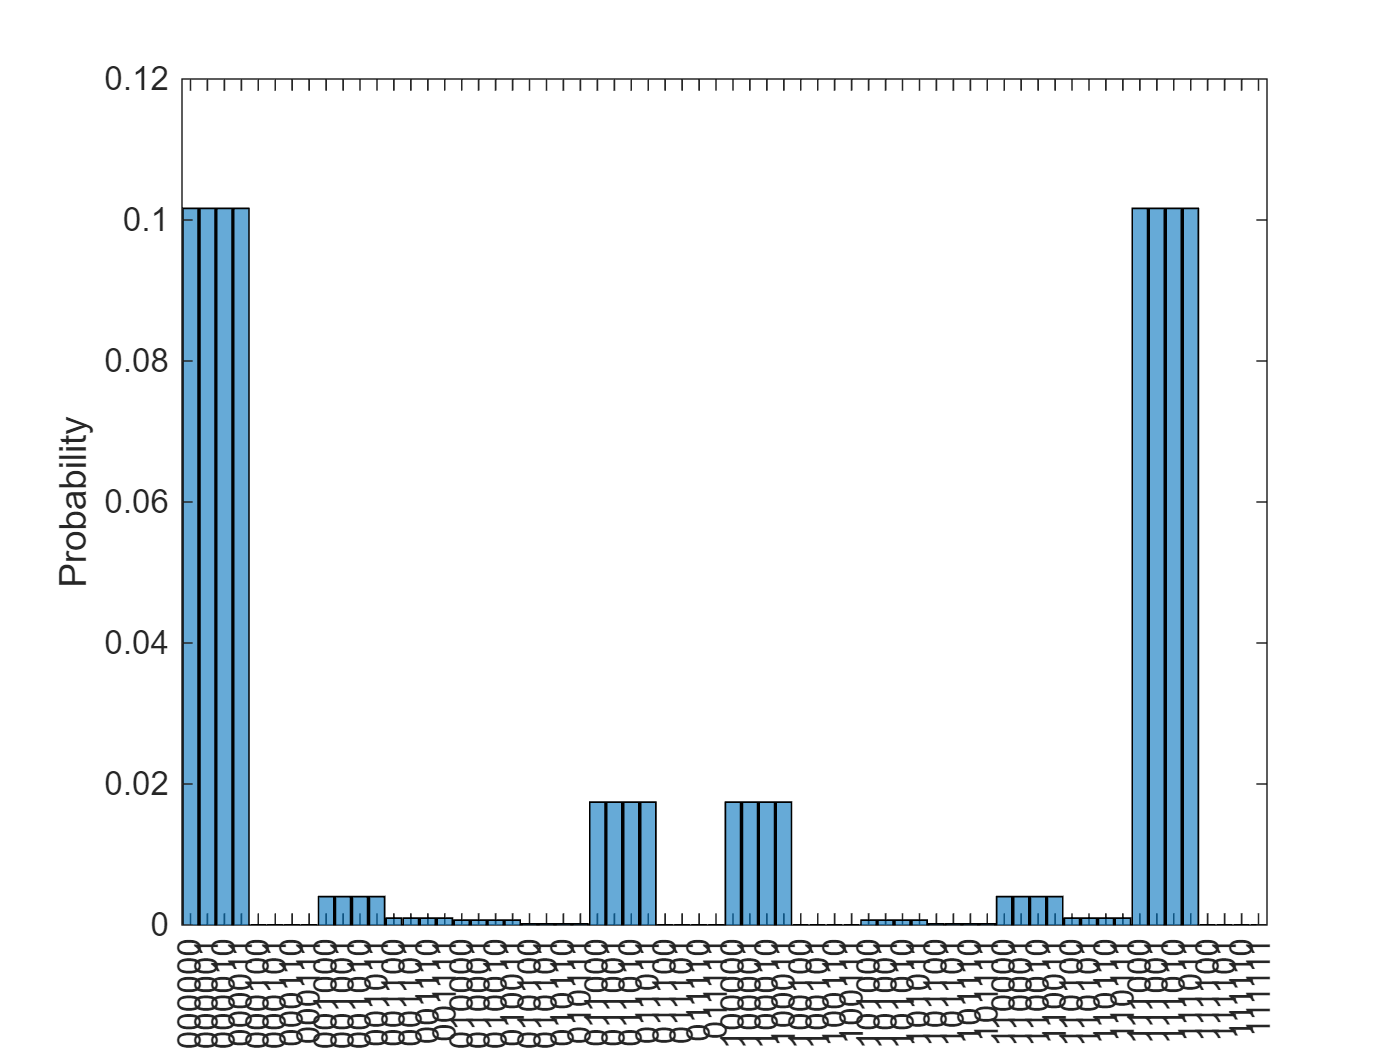

histogram(S)